% 16-714 Advanced Control for Robotics
% extra credit
% Yutong Huang
clc;clear;
close all;

% assuming C = 1 * ones(14,1) (full state)
% and the disturbances W on the control U that is N(0,0.01)
% and the disturbances V on the obs C that is N(0,0.0001)

## Initialization

global robot;
robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81]);

goal = [0.4, 0, 0.6];
x0 = homeConfiguration(robot);
x0 = [x0'; zeros(7,1)];
endEffector = "EndEffector_Link";
taskInit = getTransform(robot, x0(1:7)', endEffector);
taskFinal = trvec2tform(goal) * axang2tform([0 1 0 pi]);
ik = inverseKinematics("RigidBodyTree", robot);
xT = ik(endEffector, taskFinal, [1 1 1 1 1 1], x0(1:7)');
xT = mod(xT, 2*pi);
xT = [xT'; zeros(7,1)];

Tmax = 5;
dt = 0.05;


## Extended System Matrices for all 7 joints together

nx = 14; % 7 pos + 7 vel
nu = 7;
A = [eye(7), dt*eye(7); zeros(7), eye(7)];
B = [zeros(7), dt*eye(7)]';  % Corrected B matrix dimension
% Cost weights
Q = blkdiag(1*eye(7), 1*eye(7)); % State cost weights
R = eye(nu);  % Correct dimension for control input

% Measurement model (assuming full state observation with noise)
C = eye(nx);
V = 0.01*eye(nx);  % Measurement noise covariance matrix

% Control noise
W = 0.0001*eye(nx);  % Process noise covariance matrix

% Solve Discrete Algebraic Riccati Equation for Kalman Filter
[P, ~, ~] = dare(A', C', W, V);
Kf = P * C' / (C * P * C' + V);

% Solve Discrete Algebraic Riccati Equation for LQR
[Kc, ~] = dlqr(A, B, Q, R);
load('ref_traj.mat', 'xlist');
ref_traj = xlist;

## Joint space control Rollout (LQG)

u = @(x_hat) -Kc * (x_hat - xT);
f = @(x, u) A * x + B * u + sqrt(W) * randn(nx, 1);
c = @(x) C * x + sqrt(V) * randn(nx, 1);

% Simulate Trajectory with Kalman Filter
tlist = 0:dt:Tmax;
xlist = zeros(size(x0,1), length(tlist));
xlist(:,1) = x0; 

x_hat = x0; 
x_hat_list = zeros(size(x0,1), length(tlist));
x_hat_list(:,1) = x_hat;
ulist = zeros(size(u(x_hat),1), length(tlist)-1); % Control inputs
% Rollout
for k = 1:length(ulist)
    % Predict Step
    u_curr = u(x_hat);
    x_hat_pred = A * x_hat + B * u_curr;

    % Apply control to the true system
    xlist(:,k+1) = f(xlist(:,k), u_curr);

    % Measurement
    z = c(xlist(:,k+1));

    % Update Step
    x_hat = x_hat_pred + Kf * (z - C * x_hat_pred);

    % Apply control to the true system
    xlist(:,k+1) = f(xlist(:,k), u_curr);
    % Store values
    x_hat_list(:,k+1) = x_hat;
    ulist(:,k) = u_curr;
end


## visualize

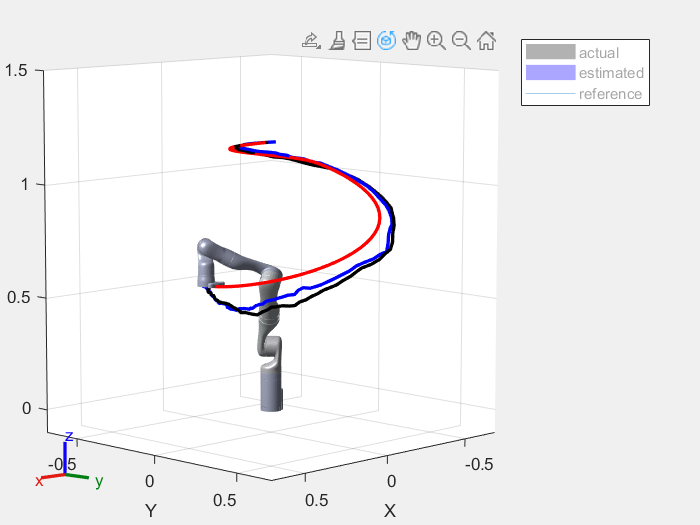

visualize_arm = 0;
figure(1); 
clist = zeros(length(tform2trvec(taskInit)),length(tlist)); 
clist(:,1) = tform2trvec(taskInit)';
c_hat_list = zeros(length(tform2trvec(taskInit)),length(tlist)); 
c_hat_list(:,1) = tform2trvec(taskInit)';
c_ref_list = zeros(length(tform2trvec(taskInit)),length(tlist)); 
c_ref_list(:,1) = tform2trvec(taskInit)';
for k = 2:length(tlist)
    x = xlist(1:7,k)';
    if visualize_arm
        pause(dt);
        show(robot,x,'PreservePlot',true,'Frames','off');
        axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
    end
    clist(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
for k = 2:length(tlist)
    x = x_hat_list(1:7,k)';
    c_hat_list(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
for k = 2:length(tlist)
    x = ref_traj(1,:,k);
    c_ref_list(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
show(robot,x,'PreservePlot',true,'Frames','off');
axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
hold on;
plot3(clist(1,:),clist(2,:),clist(3,:),'k','LineWidth',2);
hold on;
plot3(c_hat_list(1,:),c_hat_list(2,:),c_hat_list(3,:),'b','LineWidth',2);
axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
hold on;
plot3(c_ref_list(1,:),c_ref_list(2,:),c_ref_list(3,:),'r','LineWidth',2);
legend(["actual" "estimated" "reference"]);

## plot control tarj

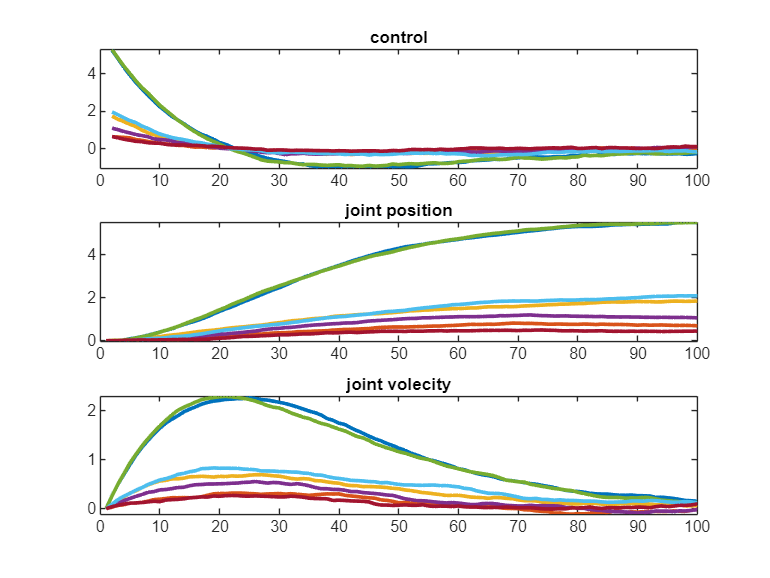

figure(2);
subplot(3,1,1)
plot(2:length(tlist), ulist,'LineWidth',2);
title("control")
xlim([0 100])
subplot(3,1,2)
plot(1:length(tlist), xlist(1:7,:),'LineWidth',2);
title("joint position")
xlim([0 100])
subplot(3,1,3)
plot(1:length(tlist), xlist(8:end,:),'LineWidth',2); 
title("joint volecity")
xlim([0 100])